# Example 6.18: Weight Matrix for 2D Gaussian Filter

Note: this script reproduces Example 6.18 (Section 6.3.5) of **Statistics for Chemical Engineers**: a 2D Gaussian filter on a 10 x 10 window with sigma = sqrt(2). Victor Z UW-Madison, 2020 illustrate 2D Gauss filter

clc;  clear all; close all hidden; format short 

## Filter weights

specify mean and covariance

   mu = [0 0];
Sigma = [2 0; 0 2]; % no correlation

% evaluate probability density function in domain(-3,3 and -3,3)
nmesh = 10;
x1 = linspace(-3,3,nmesh); x2 = linspace(-3,3,nmesh); 
[X1,X2] = meshgrid(x1,x2); % create mesh
F = mvnpdf([X1(:) X2(:)],mu,Sigma); % pdf on mesh
F = reshape(F,length(x2),length(x1));

Fc=round(100*F)

Fc =      0     0     0     1     1     1     1     0     0     0
     0     1     1     2     2     2     2     1     1     0
     0     1     2     3     4     4     3     2     1     0
     1     2     3     5     6     6     5     3     2     1
     1     2     4     6     8     8     6     4     2     1
     1     2     4     6     8     8     6     4     2     1
     1     2     3     5     6     6     5     3     2     1
     0     1     2     3     4     4     3     2     1     0
     0     1     1     2     2     2     2     1     1     0
     0     0     0     1     1     1     1     0     0     0


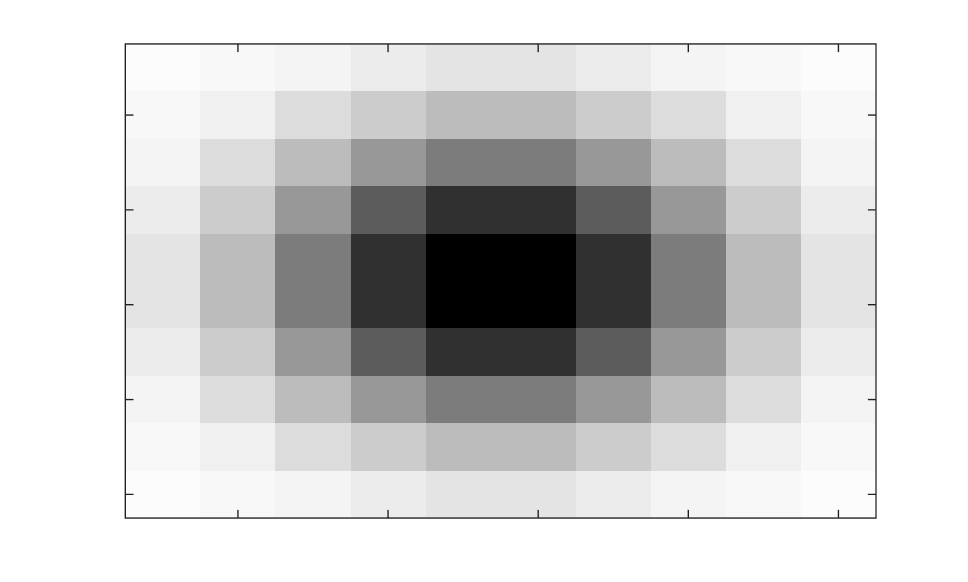


figure(1)
c=linspace(0.99,0.0,64)';
C=[c,c,c];
imagesc(100*F)
colormap(C);
set(gca,'FontSize',14)
set(gca,'xticklabel',[])
set(gca,'yticklabel',[])
print -depsc ch6_2D_gaussian_field.eps


%input.data = Fc;
%input.dataFormat = {'%.0f'};
%input.makeCompleteLatexDocument = 1;
%latex = latexTable(input);

% save LaTex code as file
% fid=fopen('MyMatrix.tex','w');
% [nrows,ncols] = size(latex);
% for row = 1:nrows
%     fprintf(fid,'%s\n',latex{row,:});
% end
% fclose(fid);

## Note

As in the book, the filter is symmetric around its center, where it is largest, and decays quickly away from it.